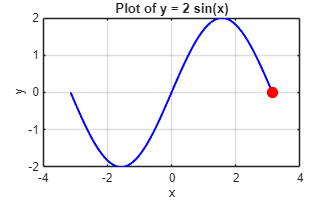

x = linspace(-pi, pi, 100);
y = 2 * sin(x);

figure;
plot(x, y, 'b', 'LineWidth', 1.5);
hold on;
xlabel('x');
ylabel('y');
title('Plot of y = 2 sin(x)');
grid on;

% Initialize marker
hMarker = plot(x(1), y(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Animation loop
for k = 1:length(x)
    % Update marker position
    set(hMarker, 'XData', x(k), 'YData', y(k));

    pause(0.05); % Adjust for animation speed
end

hold off;